% Q1 - load dataset
loaded_data = load('Exercise_8_data.mat');
data = loaded_data.data;
event = loaded_data.event;

num_records = numel(data);

% Check for missing/damaged records
damaged_idx = [];
for i = 1:num_records
    x = data(i).x;
    t = data(i).time;
    if any(isnan(x)) || any(isnan(t)) || length(x) ~= length(t)
        damaged_idx(end+1) = i;
    end
end
fprintf('Damaged record(s): %s\n', mat2str(damaged_idx));

Damaged record(s): 57


fprintf('Record %d - NaNs in x: %d, NaNs in time: %d\n', ...
    damaged_idx(1), sum(isnan(data(damaged_idx(1)).x)), sum(isnan(data(damaged_idx(1)).time)));

Record 57 - NaNs in x: 0, NaNs in time: 10001



% Visual Exploration & Log-Log Dynamic Range plot
% ** Set to 'false' to skip over this
run_visual_exploration = false; 

if run_visual_exploration
    f = figure('Name', 'Time Series & Log-Log Dynamic Range Flipbook', 'Position', [100, 100, 1000, 400]); 
    
    for i = 1:num_records
        % Skip damaged Record 57
        if ismember(i, damaged_idx)
            continue; 
        end
        
        figure(f);
        
        % Left Subplot: Standard Time Series Trace
        subplot(1, 2, 1);
        plot(data(i).time, data(i).x, 'b');
        grid on;
        title(sprintf('Record %d of %d (Time Series Trace)', i, num_records));
        xlabel('Time'); 
        ylabel('Amplitude (x)');
        
        % Right Subplot: Log-Log Dynamic Range Check
        % Sort absolute amplitudes in descending order to test for power-law structure
        x_mag = sort(abs(data(i).x), 'descend');
        
        subplot(1, 2, 2);
        loglog(x_mag, 'r', 'LineWidth', 1.5);
        grid on;
        title(sprintf('Record %d Log-Log Dynamic Range', i));
        xlabel('Rank Index (Log Scale)'); 
        ylabel('|Amplitude| (Log Scale)');
        
        pause(0.5); 
    end
end

% Dynamic range across records
mins = zeros(num_records, 1);
maxs = zeros(num_records, 1);
spans = zeros(num_records, 1);
iqrs  = zeros(num_records, 1);

for i = 1:num_records
    mins(i) = min(data(i).x);
    maxs(i) = max(data(i).x);
    spans(i) = maxs(i) - mins(i);

    % IQR (Q3 - Q1) measures the middle 50% of data to protect against outliers
    iqrs(i)  = iqr(data(i).x); 
end

fprintf('--- Dynamic Range Summary across %d records ---\n', num_records);

--- Dynamic Range Summary across 100 records ---


fprintf('Linear Span (max - min): min = %.2f, max = %.2f, mean = %.2f\n', ...
    min(spans), max(spans), mean(spans));

Linear Span (max - min): min = 97.39, max = 279.51, mean = 161.08


fprintf('IQR (Q3 - Q1)   : min = %.2f, max = %.2f, mean = %.2f\n', ...
    min(iqrs), max(iqrs), mean(iqrs));

IQR (Q3 - Q1)   : min = 5.20, max = 70.37, mean = 25.43




% Sampling interval check (skip damaged Record 57)
valid_idx = setdiff(1:num_records, damaged_idx);
dt_mean   = zeros(length(valid_idx), 1);
dt_std    = zeros(length(valid_idx), 1);
dt_min_raw = zeros(length(valid_idx), 1);
dt_min_robust = zeros(length(valid_idx), 1);
zero_dt_count = 0;

for k = 1:length(valid_idx)
    dt = diff(data(valid_idx(k)).time);
    
    % Check for duplicate timestamps (dt == 0)
    zero_dt_count = zero_dt_count + sum(dt == 0);
    
    % Filter only positive intervals (dt > 0)
    pos_dt = dt(dt > 0);
    
    dt_mean(k) = mean(pos_dt);
    dt_std(k)  = std(pos_dt);
    
    % Raw absolute minimum (vulnerable to rare clock stutters)
    dt_min_raw(k) = min(pos_dt);
    
    % "Within Reason" Robust Minimum: 1st percentile ignores rare bottom 1% stutters
    dt_min_robust(k) = prctile(pos_dt, 1); 
end

fprintf('--- Sampling Interval Characteristics ---\n');

--- Sampling Interval Characteristics ---


fprintf('Total duplicate timestamps (dt == 0) found across records: %d\n', zero_dt_count);

Total duplicate timestamps (dt == 0) found across records: 99


fprintf('Mean sampling interval range    : [%.2f, %.2f]\n', min(dt_mean), max(dt_mean));

Mean sampling interval range    : [10.00, 10.00]


fprintf('Sampling interval std range     : [%.2f, %.2f]\n', min(dt_std), max(dt_std));

Sampling interval std range     : [2.19, 3.00]


fprintf('Avg coefficient of variation    : %.1f%%\n', mean(dt_std ./ dt_mean) * 100);

Avg coefficient of variation    : 26.2%


fprintf('Raw minimum interval range      : [%.5f, %.5f] (Would cause RAM explosion!)\n', min(dt_min_raw), max(dt_min_raw));

Raw minimum interval range      : [0.00257, 2.48705] (Would cause RAM explosion!)


fprintf('Robust minimum ("within reason"): [%.2f, %.2f] (1st percentile threshold)\n', min(dt_min_robust), max(dt_min_robust));

Robust minimum ("within reason"): [2.92, 5.00] (1st percentile threshold)




% Quantization check - Count unique amplitude values (Task 1d, bullet 3)
dup_frac   = zeros(num_records, 1);
num_unique = zeros(num_records, 1);
min_delta  = zeros(num_records, 1);

for i = 1:num_records
    x = data(i).x;
    u_vals = unique(x);
    
    num_unique(i) = length(u_vals);
    dup_frac(i)   = 1 - num_unique(i) / length(x);
    
    % Find empirical quantization step size (minimum difference between unique values)
    min_delta(i)  = min(diff(u_vals));
end

fprintf(' Coarse Quantization Check:\n');

 Coarse Quantization Check:


fprintf('Unique amplitude count range : [%d, %d] out of ~10,000 samples\n', min(num_unique), max(num_unique));

Unique amplitude count range : [10001, 10001] out of ~10,000 samples


fprintf('Max duplicate-value fraction : %.4f\n', max(dup_frac));

Max duplicate-value fraction : 0.0000


fprintf('Empirical min step size (Δ)  : min = %.2e, max = %.2e\n', min(min_delta), max(min_delta));

Empirical min step size (Δ)  : min = 2.58e-09, max = 2.20e-06


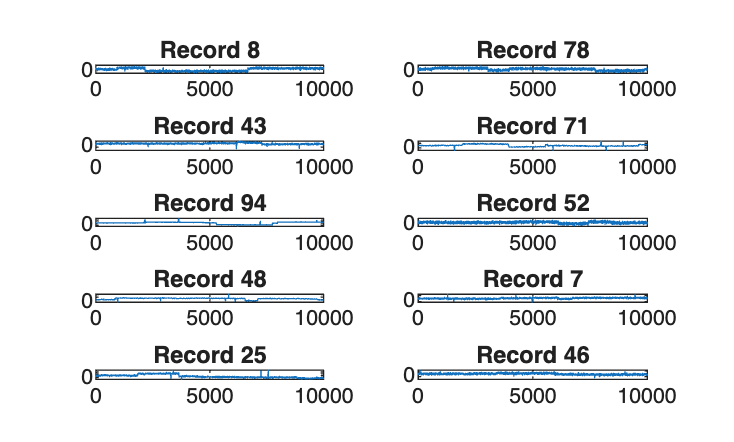



% Plot 10 randomly selected records
rng(7);
sample_idx = randperm(num_records, 10);

figure;
for k = 1:10
    subplot(5, 2, k);
    plot(data(sample_idx(k)).x);
    title(sprintf('Record %d', sample_idx(k)));
end

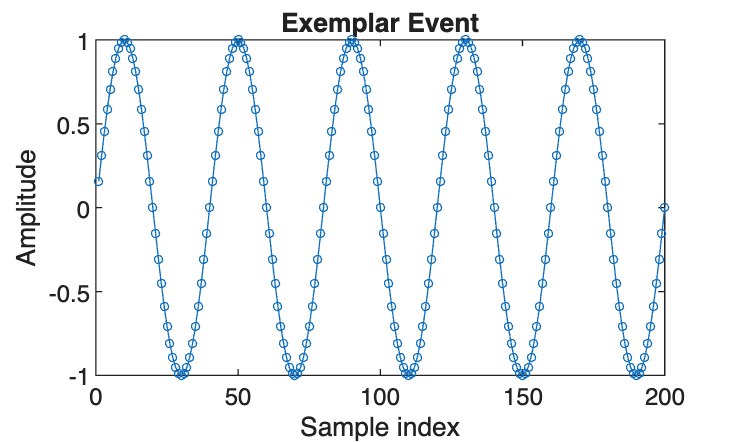


% Plot the event
figure;
plot(event, '-o', 'MarkerSize', 3);
title('Exemplar Event');
xlabel('Sample index'); ylabel('Amplitude');

Record 57 contains erroneous data, its time vector is entirely NaN even though the measurement data itself is fine, suggesting a timestamp logging fault rather than a sensor fault. Because accurate time intervals are mandatory for signal processing, record 57 is formally excluded from analysis. All remaining 99 records are kept.

Dynamic range varies a fair bit record to record, ranging from roughly 100 to 280, so normalization should probably be done per-record rather than globally. Furthermore, comparing the this linear span to the interquartile range, yielded a ratio of 6.3. The IQR is immune to single-sample outliers, whereas the min-max peak-to-peak span is not, and so this ratio gives us a sense of how many outliers we have. Even without calculating this ration, our visual flipping through the data made it obvious that these exist and need to be removed. Finally, we created log-log plots of the histograms of the amplitude against the rank-index. This plot confirmed a linear dynamic range with flat curves that steeply fall at the far right edge.

Analysis of the inter-arrival times led to 3 notable insights. First, every valid record shows a mean sampling interval of about 10, but with a standard deviation around 25–30% of that, this is genuinely stochastic sampling, consistently across the whole dataset, not just a few noisy records. Second, every single record had one pair of samples with identical timestamps. These need to be de-duplicated prior to interpolation. Finally, to correct for stochastic sampling, we need to interpolate the data onto a uniform time grid. As we discussed, using the absolute raw minimum interval (~0.00257) wouldn't be practical, as it would expand a single record into 39 million samples. Instead, we use the 1st percentile of positive intervals to get a reasonable minimum arrival time of 3.88.

Evaluating the ratio of unique amplitude values confirmed that there is no coarse quantization. Every record contains between 9,998 and 10,001 unique values out of 10,000 samples, exceeding the 64-cell threshold required to resolve the signal. Following Bennett's (1948) theorem, the empirical quantization step size (~10^-15) is much smaller than the signal variance, allowing quantization error to be treated as white noise.

Visual inspection of the records show that the same basic statistical class seems to be present among them. We do see three different kinds of artifacts: 1. isolated outlier spikes , as noted above. We can use median filtering to remove these. 2. Varying amounts of background noise per time series, which can be addressed via wavelet denoising. 3. Sudden vertical level shifts, with the underlying physical signal unchanged on both sides of the jump (stationarity holds). These appear to be sensor issues that can be subtracted out of the signal.

The event itself is a clean, smooth, ~5-cycle sinusoidal burst with no noise, easy to recognize in isolation, but given the noise, spikes and shifts noted above in the records, finding it reliably embedded in real data is a different problem entirely. Stochastic sampling will also stretch and compress the event's time duration between time series, causing misalignment that will make this difficult.

% Q2 - Baseline Assessment: Vectorized Matched Filtering on Raw Data
L = length(event);

% Pre-normalize the event template
y_zero = event - mean(event);
y_norm = y_zero / norm(y_zero);

best_corr = zeros(num_records, 1);
best_pos  = zeros(num_records, 1);

for i = 1:num_records
    if ismember(i, damaged_idx)
        continue;
    end
    x = data(i).x;
    
    % Vectorized Numerator (Sliding dot product via fast convolution)
    num_vec = conv(x, flipud(y_norm), 'valid');
    
    % Vectorized Denominator (Sliding local L2 norm via moving standard deviation)
    den_vec = sqrt(L - 1) * movstd(x, [L-1, 0], 'Endpoints', 'discard');
    
    % Compute normalized correlation coefficient for all indices
    corrs = num_vec ./ (den_vec + eps);
    
    [best_corr(i), best_pos(i)] = max(corrs);
end

% Find global maximum correlation across the entire dataset
[global_max_corr, best_record] = max(best_corr);
global_best_pos = best_pos(best_record);

fprintf('Vectorized Matched Filter Results (Step Size = 1) \n');

Vectorized Matched Filter Results (Step Size = 1) 


fprintf('Max correlation across all records: %.4f (found in Record %d at Index %d)\n', ...
    global_max_corr, best_record, global_best_pos);

Max correlation across all records: 0.7328 (found in Record 23 at Index 8416)



% Grab the 10 strongest matches
[sorted_corr, sort_idx] = sort(best_corr, 'descend');
top10_records = sort_idx(1:10);
top10_pos = best_pos(top10_records);

fprintf('Top 10 Matched Filter Matches on Raw Data:\n');

Top 10 Matched Filter Matches on Raw Data:


for k = 1:10
    fprintf('  %2d. Record %2d at Index %5d | Correlation: %.4f\n', ...
        k, top10_records(k), top10_pos(k), sorted_corr(k));
end

   1. Record 23 at Index  8416 | Correlation: 0.7328
   2. Record 65 at Index  6848 | Correlation: 0.6987
   3. Record 94 at Index  8446 | Correlation: 0.6906
   4. Record 53 at Index  1959 | Correlation: 0.6889
   5. Record 34 at Index  3381 | Correlation: 0.6464
   6. Record 55 at Index  7115 | Correlation: 0.6346
   7. Record 14 at Index   489 | Correlation: 0.6327
   8. Record 43 at Index  9555 | Correlation: 0.6315
   9. Record 64 at Index  2086 | Correlation: 0.6262
  10. Record 77 at Index   706 | Correlation: 0.6242


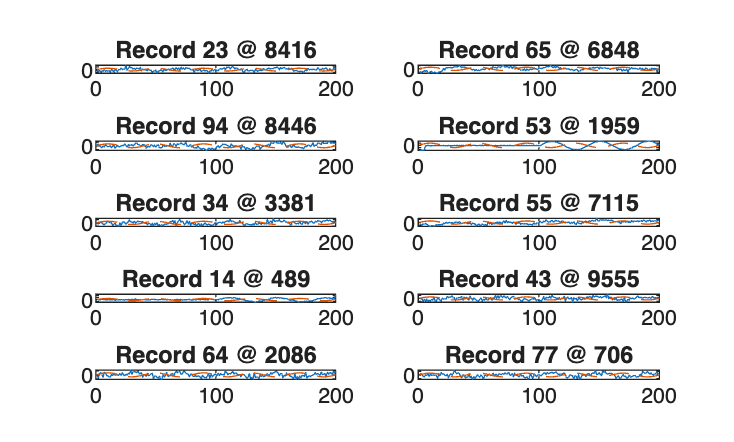


% Plot the 10 found examples against the event template
figure;
for k = 1:10
    subplot(5, 2, k);
    rec = top10_records(k);
    pos = top10_pos(k);
    seg = data(rec).x(pos:pos+L-1);
    seg_z = (seg - mean(seg)) / std(seg);
    plot(seg_z); hold on;
    plot(event, '--');
    title(sprintf('Record %d @ %d', rec, pos));
    hold off;
end

The strongest matches only reach correlation coefficients around 0.68 to 0.73. These should be around 1.0, which tells us right away that no occurrence of the event in the actual data is a clean, unaltered copy of the exemplar. Each occurrence is embedded in noise, sits at a different amplitude/scale (even over the course of a single series - see record 14) depending on that record's own dynamic range, and shows frequency mismatches consistent with the stochastic sampling we found in Q1.

So the 10 highest-scoring windows do have sinusoidal oscillations, but the correlation scores are too low to confidently conclude these are true event detections. One problem is that we are working are in sample space, not actual time space. Because of stochastic sampling, this means that the actual time-spacing of the filter and the signal aren't matching at all. Therefore, we can see how poorly matched filtering performs on the raw signal, which stresses just how crucial it is to pre-process this data - particularly resampling onto a uniform time grid - before matched filtering can be applied.

To build a system to automatically detect events, a vectorized sliding matched filter using convolution would scan all window positions at once rather than via a loop. This allows us to work on huge datasets without manual inspection. However, it wouldn't be able to detect all variations. The matched filter works very well if we know the exact shape of the signal we are detecting. Stochastic sampling distorts the event's frequency in sample space. Also, vertical shifts occurring within a window would corrupt mean and standard deviation estimates in normalization, causing filter mismatches. If we want to reliably detect all variations, preprocessing must be done including denoising, resampling to a uniform time grid and level-shift correction.

A neural network by itself isn't a good solution here either. We only have ~100 records total, giving very few labeled true-positive examples to train on, nowhere near enough for a network to learn robust invariance to amplitude scaling, timing jitter, and noise on its own. A plain feedforward network has no built-in translation or time-warp invariance, so it would need to see the event at every possible position/scale/noise condition during training to generalize, which this dataset can't provide. A correlation/matched-filter approach, by contrast, directly exploits the fact that we already know the exact shape we're looking for and needs no training data at all; it's simpler, more data-efficient, and more interpretable for this specific problem.

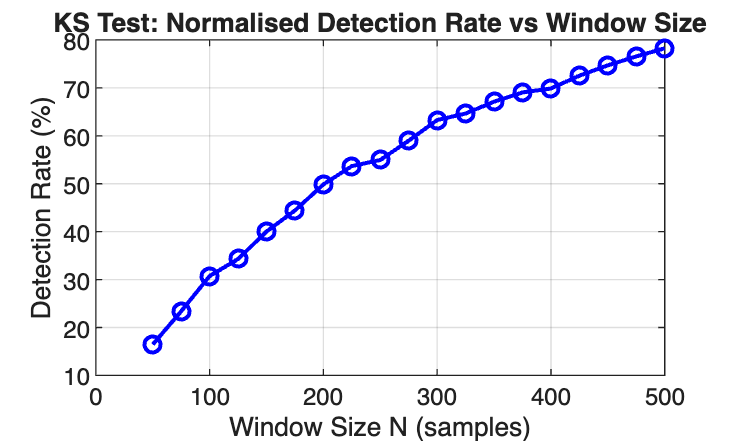

% Q3 Sweep window sizes finely to find the sweet spot for KS test
window_sizes = 50:25:500;
alpha = 0.05;
detection_rate = zeros(length(window_sizes), 1);

for wi = 1:length(window_sizes)
    w = window_sizes(wi);
    total_tests = 0;
    total_detections = 0;
    
    for i = 1:num_records
        if ismember(i, damaged_idx)
            continue;
        end
        x = data(i).x;
        n = length(x);
        
        for j = 1:w:(n - 2*w + 1)
            win1 = x(j     : j +   w - 1);
            win2 = x(j + w : j + 2*w - 1);
            [~, p] = kstest2(win1, win2);
            total_tests = total_tests + 1;
            if p < alpha
                total_detections = total_detections + 1;
            end
        end
    end
    
    detection_rate(wi) = total_detections / total_tests;
end

figure('Name', 'KS Test Detection Rate vs Window Size');
plot(window_sizes, detection_rate * 100, 'b-o', 'LineWidth', 1.5);
grid on;
xlabel('Window Size N (samples)');
ylabel('Detection Rate (%)');
title('KS Test: Normalised Detection Rate vs Window Size');



% Stationarity Testing via Two-Sample KS Test
N_win = 100;   % Window size chosen from power analysis
alpha = 0.05;  % Significance level
stride = N_win; % Non-overlapping windows for independent comparisons

% Pre-allocate summary statistics
pct_rejected = zeros(num_records, 1); % Fraction of window pairs rejecting H0

figure('Name', 'Q3: KS Stationarity Test - P-Value Profiles');

for i = 1:num_records
    if ismember(i, damaged_idx)
        continue;
    end
    x = data(i).x;
    n = length(x);

    % Slide two adjacent windows from left to right at stride = N_win
    positions = [];
    p_vals    = [];

    for j = 1 : stride : (n - 2*N_win + 1)
        win1 = x(j          : j +   N_win - 1);
        win2 = x(j + N_win  : j + 2*N_win - 1);

        [~, p] = kstest2(win1, win2);

        positions(end+1) = j + N_win; %#ok<SAGROW> Midpoint between the two windows
        p_vals(end+1)    = p;         
    end

    pct_rejected(i) = mean(p_vals < alpha) * 100;
end

% Summary across all valid records
fprintf('--- Q3 Stationarity Testing Summary (N = %d, alpha = %.2f) ---\n', N_win, alpha);

--- Q3 Stationarity Testing Summary (N = 100, alpha = 0.05) ---


fprintf('Mean rejection rate across records : %.1f%%\n', mean(pct_rejected(pct_rejected > 0)));

Mean rejection rate across records : 30.7%


fprintf('Min rejection rate                 : %.1f%%\n', min(pct_rejected(pct_rejected > 0)));

Min rejection rate                 : 7.1%


fprintf('Max rejection rate                 : %.1f%%\n', max(pct_rejected(pct_rejected > 0)));

Max rejection rate                 : 94.9%


fprintf('Records with > 50%% rejection rate  : %d of 99\n', sum(pct_rejected > 50));

Records with > 50% rejection rate  : 15 of 99


fprintf('Records with < 10%% rejection rate  : %d of 99\n', sum(pct_rejected > 0 & pct_rejected < 10));

Records with < 10% rejection rate  : 1 of 99


A two-sample Kolmogorov-Smirnov test was applied to adjacent non-overlapping windows sliding across each of the 99 valid records. A window size of 100 was chosen because this is the smallest window size that can still provide enough statistical power (at alpha = 0.05). We plotted window size against KS test detection rate, and no plateau or elbow was seen, which confirms that there is no optimal window size to choose, which is why we defaulted to 100.

The average rejection rate across all records was 30.7%, much higher than the 5% expected under H0, that the signal is stationary. In fact, even the minimum rejection rate across all 99 time series was higher than 5% (at 7.1%). Therefore, the data cannot be modeled as arising from a stationary (or ergodic) process. Since ergodicity requires stationarity, it is ruled out as well. We noted vertical level-shifts in Q1 and this is the likely source of the non-stationarity that we see here.

% Q4 - Characterize the stochastic sampling distribution
all_dts = [];

for i = 1:num_records
    if ismember(i, damaged_idx)
        continue;
    end
    dt = diff(data(i).time);

    % Keep only positive intervals (exclude duplicate timestamps dt == 0)
    all_dts = [all_dts; dt(dt > 0)];
end

% Apply 1st percentile "within reason" threshold from Q1
dt_threshold = prctile(all_dts, 1);
valid_dts = all_dts(all_dts >= dt_threshold);

fprintf('--- Stochastic Sampling Distribution Characteristics ---\n');

--- Stochastic Sampling Distribution Characteristics ---


fprintf('Total valid intervals : %d\n', length(valid_dts));

Total valid intervals : 979902


fprintf('Mean  (mu)            : %.4f\n', mean(valid_dts));

Mean  (mu)            : 10.0681


fprintf('Std   (sigma)         : %.4f\n', std(valid_dts));

Std   (sigma)         : 2.5495


fprintf('CoV                   : %.1f%%\n', std(valid_dts)/mean(valid_dts)*100);

CoV                   : 25.3%


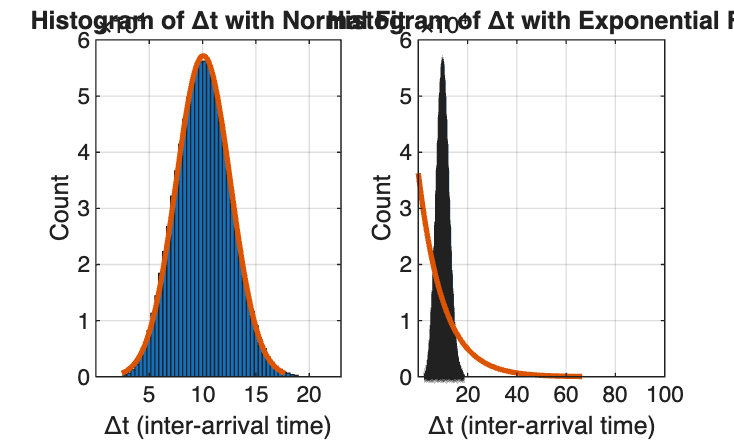


% Plot histogram with Normal and Exponential fits side-by-side
figure('Name', 'Q4: Stochastic Sampling Distribution');

subplot(1, 2, 1);
histfit(valid_dts, 60, 'normal');
title('Histogram of \Deltat with Normal Fit');
xlabel('\Deltat (inter-arrival time)'); ylabel('Count');
grid on;

subplot(1, 2, 2);
histfit(valid_dts, 60, 'exponential');
title('Histogram of \Deltat with Exponential Fit');
xlabel('\Deltat (inter-arrival time)'); ylabel('Count');
grid on;


% Formal KS goodness-of-fit test against Normal distribution
% Z-score the valid_dts and test against standard normal
dts_zscore = (valid_dts - mean(valid_dts)) / std(valid_dts);
[h_normal, p_normal, ksstat] = kstest(dts_zscore);
fprintf('KS statistic D        : %.6f (max CDF deviation = %.4f%%)\n', ksstat, ksstat * 100);

KS statistic D        : 0.007338 (max CDF deviation = 0.7338%)


fprintf('KS D_critical at 0.05 : %.6f (N = %d)\n', 1.36 / sqrt(length(dts_zscore)), length(dts_zscore));

KS D_critical at 0.05 : 0.001374 (N = 979902)



fprintf('\n--- KS Goodness-of-Fit Test ---\n');


--- KS Goodness-of-Fit Test ---


fprintf('Normal distribution  : h = %d, p = %.4f ', h_normal, p_normal);

Normal distribution  : h = 1, p = 0.0000 

if h_normal == 0
    fprintf('(FAIL TO REJECT: data is consistent with Gaussian)\n');
else
    fprintf('(REJECT: data is NOT Gaussian)\n');
end

(REJECT: data is NOT Gaussian)


The visual histogram plot suggests that the distribution of inter-arrival times is Gaussian. To formally test this, a KS test was done with D = 0.0073, p = 0); however, with a large sample of about 980,000 intervals, The critical threshold for the D statistic was 0.0014, which means CDF deviations above 0.14% are flagged as significantly different. Our observed deviation is 0.73%, which is practically negligible. In any case, even with a non-Gaussian distribution, the coefficient of variance of 25.3% indicates that there is enough stochastic variability to cause problems for matched filtering.